# Examples of Wilcoxon tests

Joël Karel, Department of Advanced Computing Sciences, Maastricht university, 2022

This file is to understand the assumptions made when doing a Wilcoxon test to test the difference in center of two distributions

# Wilcoxon signed-rank test

### Same distribution

Let the samples come from the same distribution

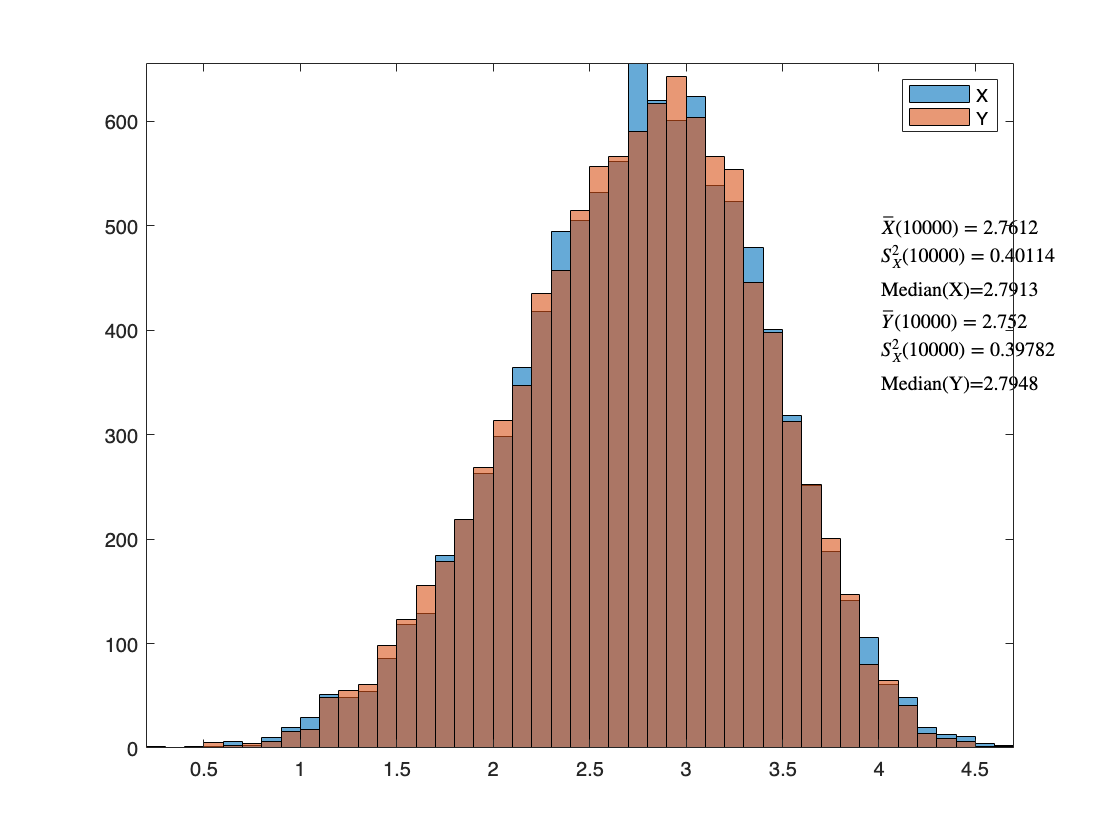

N=10000;
X=wblrnd(3,5,1,N);
Y=wblrnd(3,5,1,N);
figure;
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(4,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(4,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(4,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(4,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(4,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(4,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

We will do the thest manually first with a few simplifications to gain understanding. First we can pair the samples and compute the differences

Z=X-Y;

And their magnitudes and signs

Zm=abs(Z);
Zs=sign(Z);

Exclude the pairs that are exactly 0 (ain't gonna happen here)

Zs=Zs(Zm~=0);
Zm=Zm(Zm~=0);
Nr=length(Zs);

Sort the pairs

[Zms,I]=sort(Zm);
Zss=Zs(I);

Now we have to rank the pairs and handle ties. We're not gonna have ties, hence we are ignoring this for the sake of this example. Then we compute the test statistic W:

W=Zss*(1:Nr)'

W = 754290

For Nr>20 we have approximately a normal distribution. (Matlab will be a bit more precise)

sigmaW=sqrt((Nr*(Nr+1)*(2*Nr+1))/6);
z=W/sigmaW

z = 1.3064

This allows us to compute a p-value

p=2*normcdf(-abs(z))

p = 0.1914

if(p<0.05) 
    disp('We have something significant') 
else
    disp('We cannot reject H0')
end

We cannot reject H0


We can check that with Matlab

pm=signrank(X,Y)

pm = 0.1914

if(pm<0.05) 
    disp('We have something significant') 
else
    disp('We cannot reject H0')
end

We cannot reject H0


Ok, now we understand it and move on to more interesting cases

### Shifted distribution

Let the samples come from a similar distribution. We reject H0.

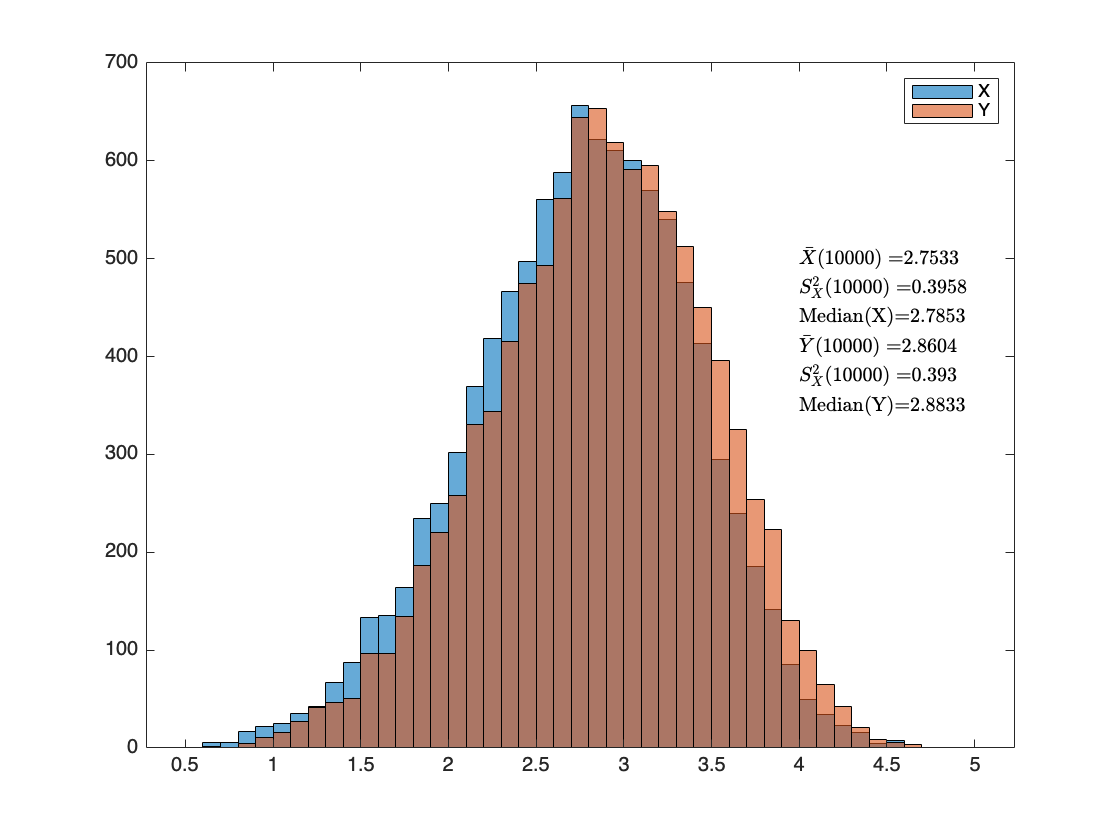

N=10000;
X=wblrnd(3,5,1,N);
Y=wblrnd(3,5,1,N)+0.1;
figure
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(4,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(4,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(4,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(4,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(4,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(4,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

pm=signrank(X,Y)

pm = 6.7773e-31

if(pm<0.05) 
    disp('We have something significant') 
else
    disp('We cannot reject H0')
end

We have something significant


### Mean the same, but distributions different

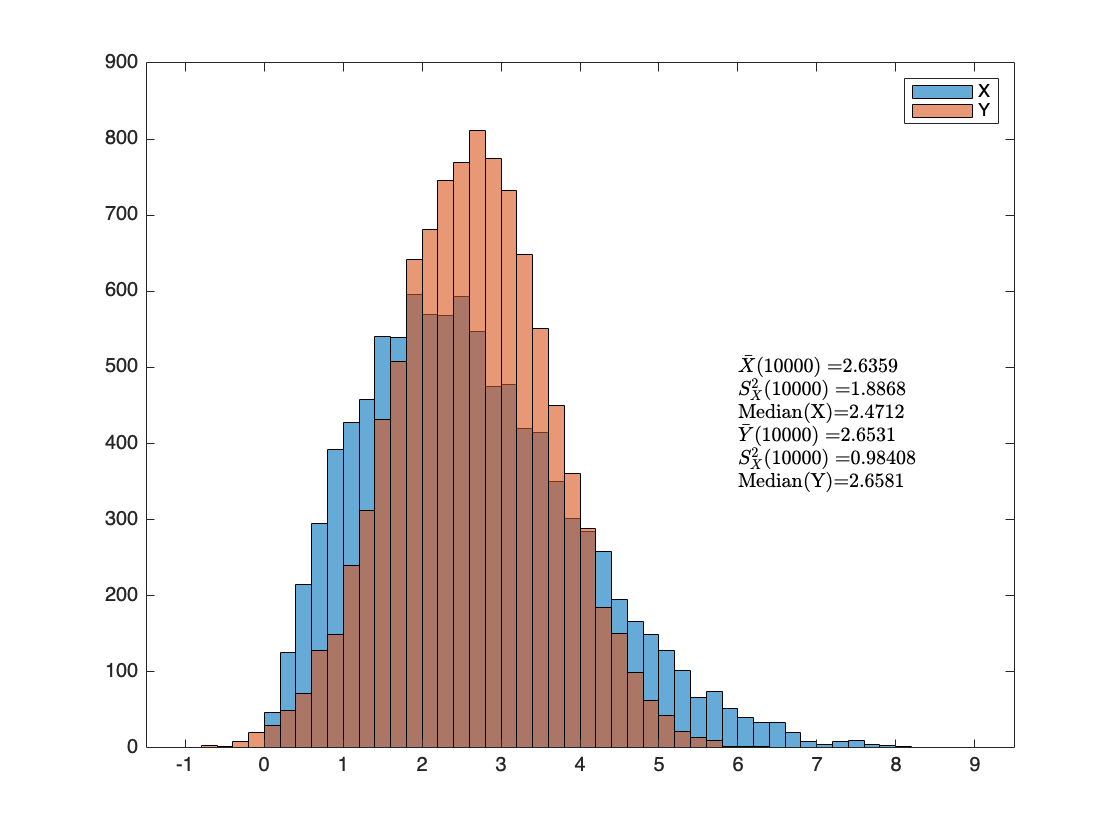

N=10000;
X=wblrnd(3,2,1,N);
Y=randn(1,N);
Y=Y+wblstat(3,2);
figure
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(6,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(6,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(6,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(6,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(6,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(6,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

figure;
mean(X-Y)

ans = -0.0172

median(X-Y)

ans = -0.1214

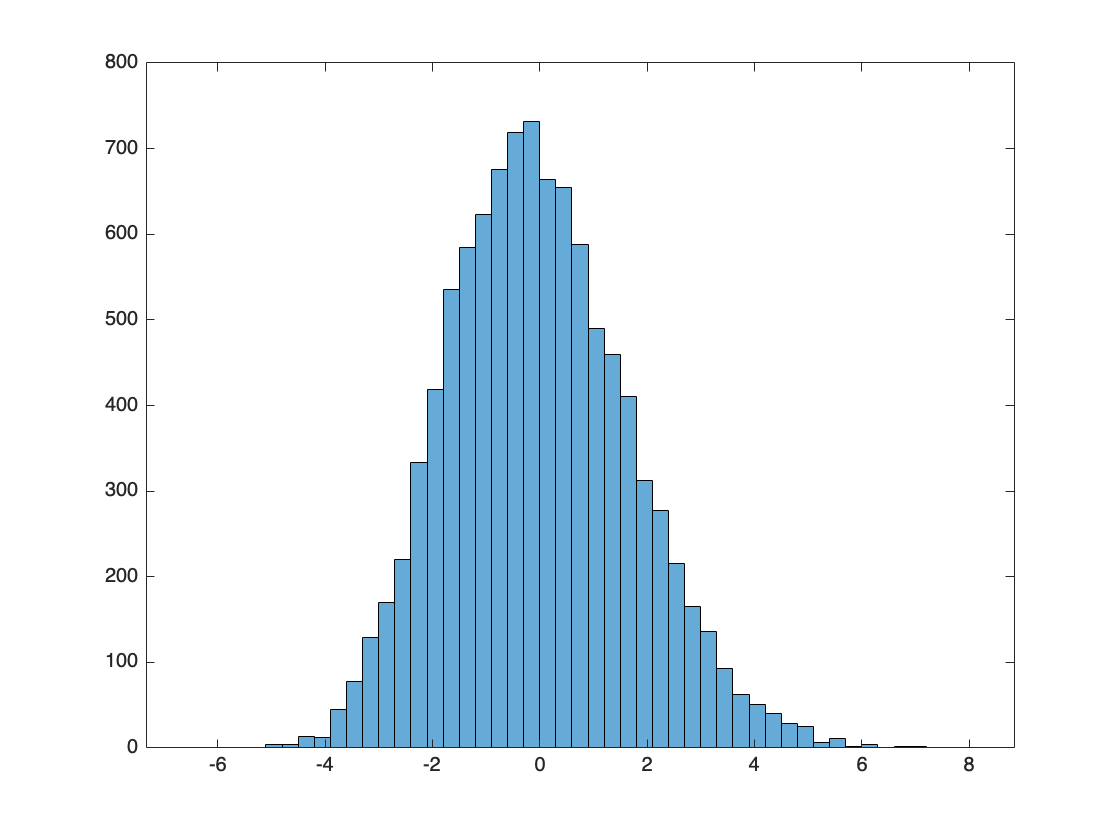

histogram(X-Y);

pm=signrank(X,Y)

pm = 1.2640e-04

if(pm<0.05) 
    disp('We have something significant') 
else
    disp('We cannot reject H0')
end

We have something significant


Quite often we will reject H0, i.e. have a significant result.

### Median the same, but distributions different

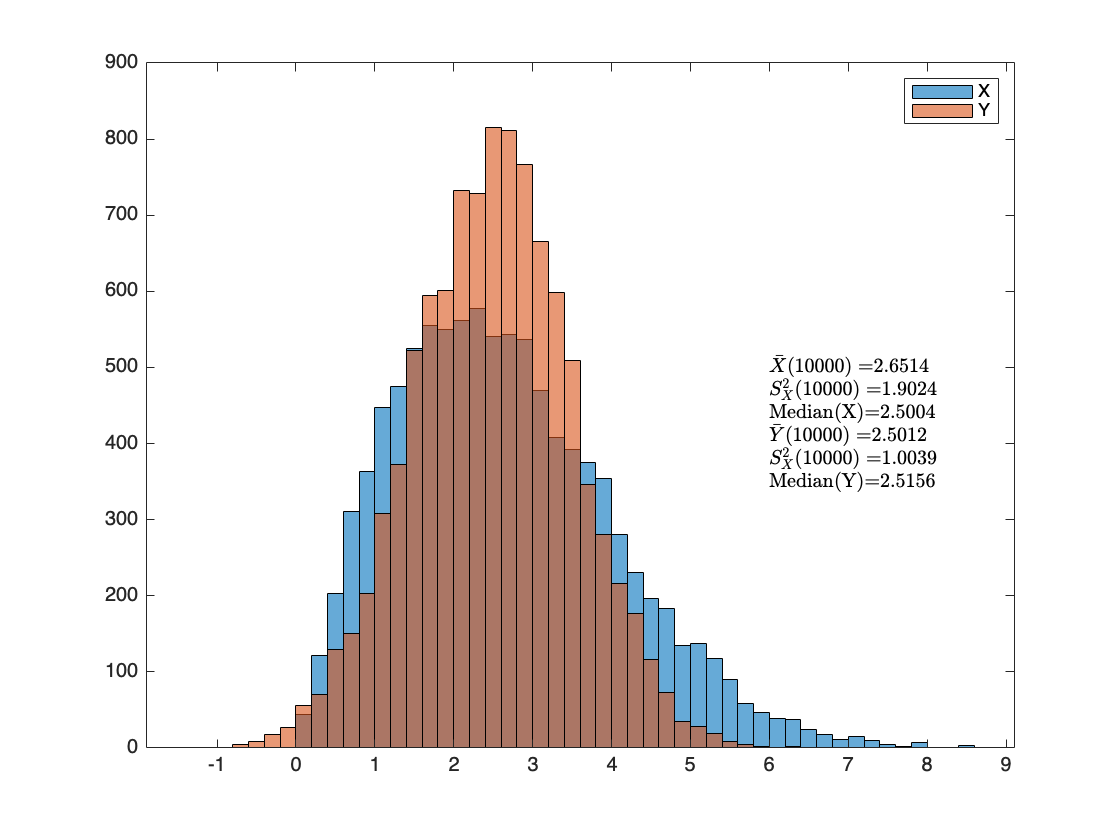

N=10000;
lambda=3;k=2;
X=wblrnd(lambda,k,1,N);
Y=randn(1,N);
Y=Y+lambda*(log(2)^(1/k));
figure
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(6,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(6,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(6,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(6,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(6,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(6,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

figure;
mean(X-Y)

ans = 0.1501

median(X-Y)

ans = 0.0558

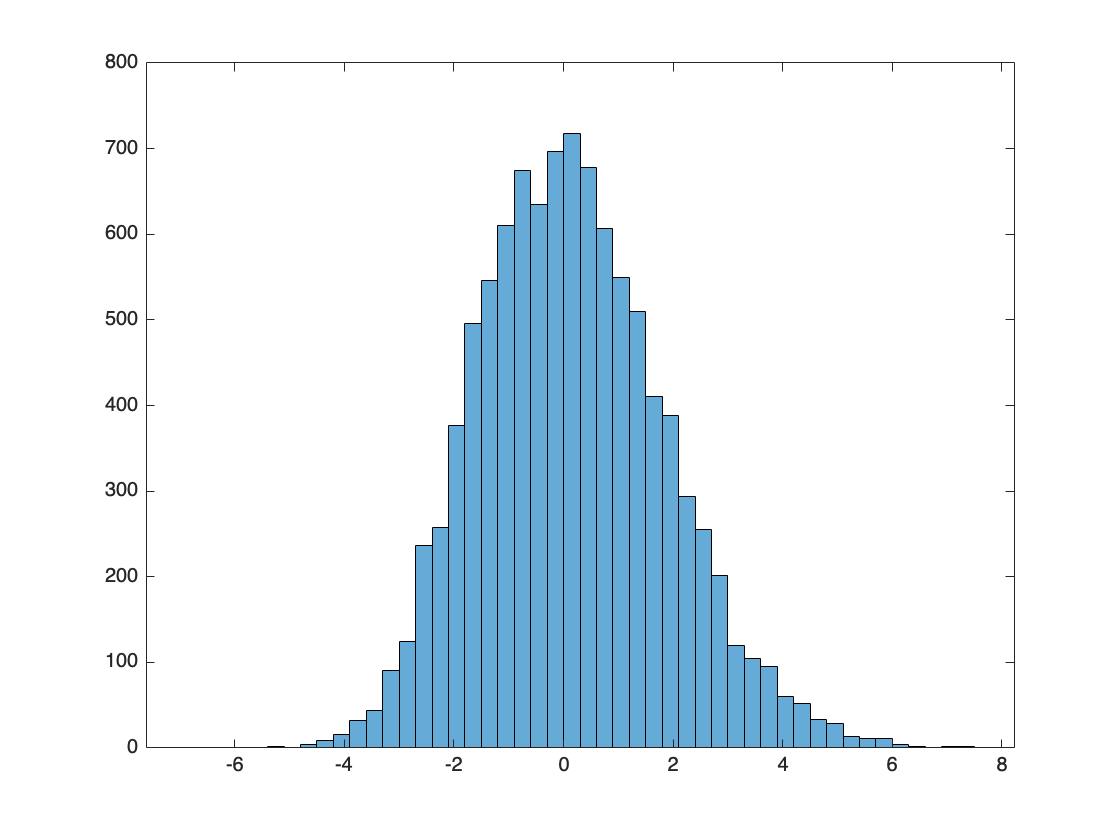

histogram(X-Y);

pm=signrank(X,Y)

pm = 6.6852e-09

if(pm<0.05) 
    disp('We have something significant') 
else
    disp('We cannot reject H0')
end

We have something significant


With the Wilcoxon signed rank test, the distribution of the difference in the paired samples; i.e. the distribution of Z must be symmetric for the signed rank test to test the difference in center of the two samples.

## Wilcoxon Rank Sum Test / Mann-Whitney U-test

### Same distribution

Let the samples come from the same distribution

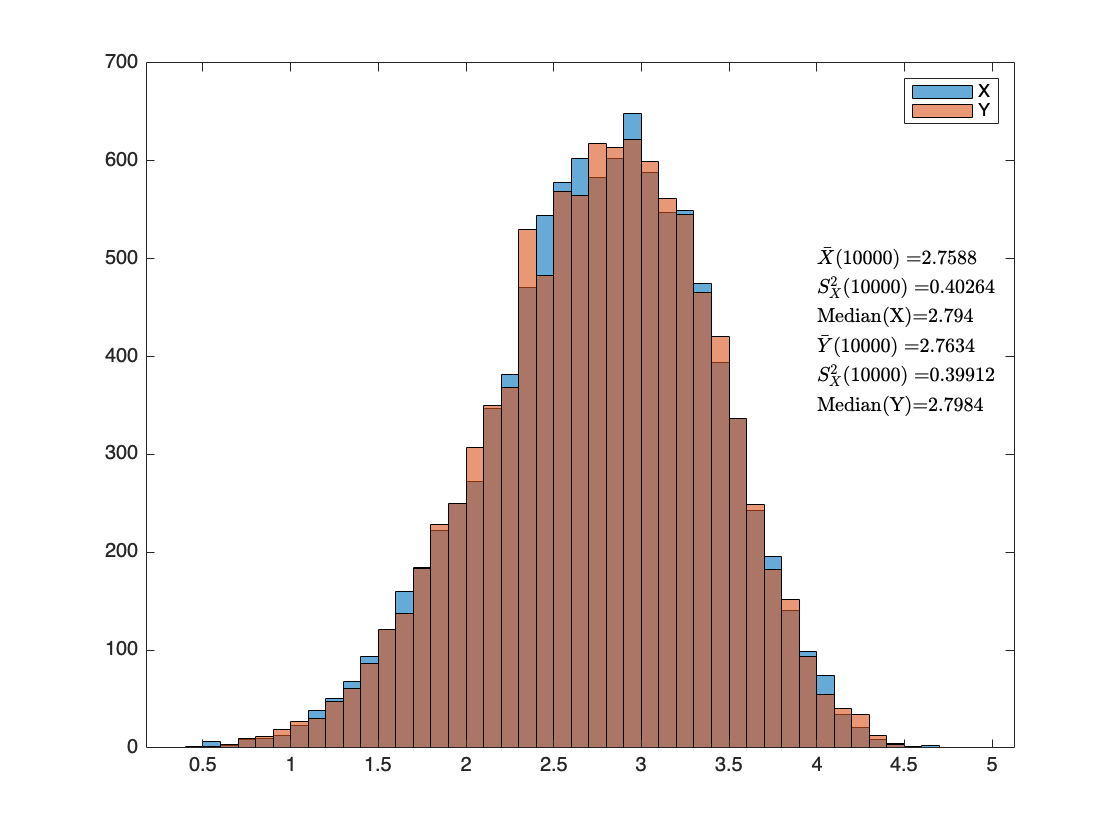

NX=10000;
NY=10000;
X=wblrnd(3,5,1,NX);
Y=wblrnd(3,5,1,NY);
figure;
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(4,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(4,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(4,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(4,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(4,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(4,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

We will first do this manually to gain understanding, but with a few simplifications that are justified in this case: We will assume that we have no equal values, otherwise we would have to assign to each of them the average rank of the equal observations. With these continuous values, that should be okay. 

now we combine the values of the two samples and keep track from which sample is which observation

merged=[X Y];
source=[zeros(1,NX) ones(1,NY)];

then we rank them by value 

[~,idx]=sort(merged);
sourcernk=source(idx);

Then we compute the rank sum for each sample

RX=sum(find(sourcernk==0))

RX = 99843307

RY=sum(find(sourcernk==1))

RY = 100166693

Then we can compute UX and UY as

UX=RX-(NX*(NX+1))/2;
UY=RY-(NY*(NY+1))/2;

and find the minimum

U=min([UX,UY])

U = 49838307

If the number of samples is large then we can use the normal approximation for the test statistic

muU=(NX*NY)/2;
sigmaU=sqrt((NX*NY*(NX+NY+1))/12) %assuming no tied ranks

sigmaU = 4.0826e+05

z=(U-muU)/sigmaU

z = -0.3961

and compute the p-value

p=2*normcdf(-abs(z))

p = 0.6921

Let's check whether Matlab has the same

[p,h,stats] = ranksum(X,Y);
p

p = 0.6921

h

h = logical
   0


stats

stats = struct with fields:
       zval: -0.3961
    ranksum: 99843307


Here we should only get a significant result by chance

### Same distribution with different spread

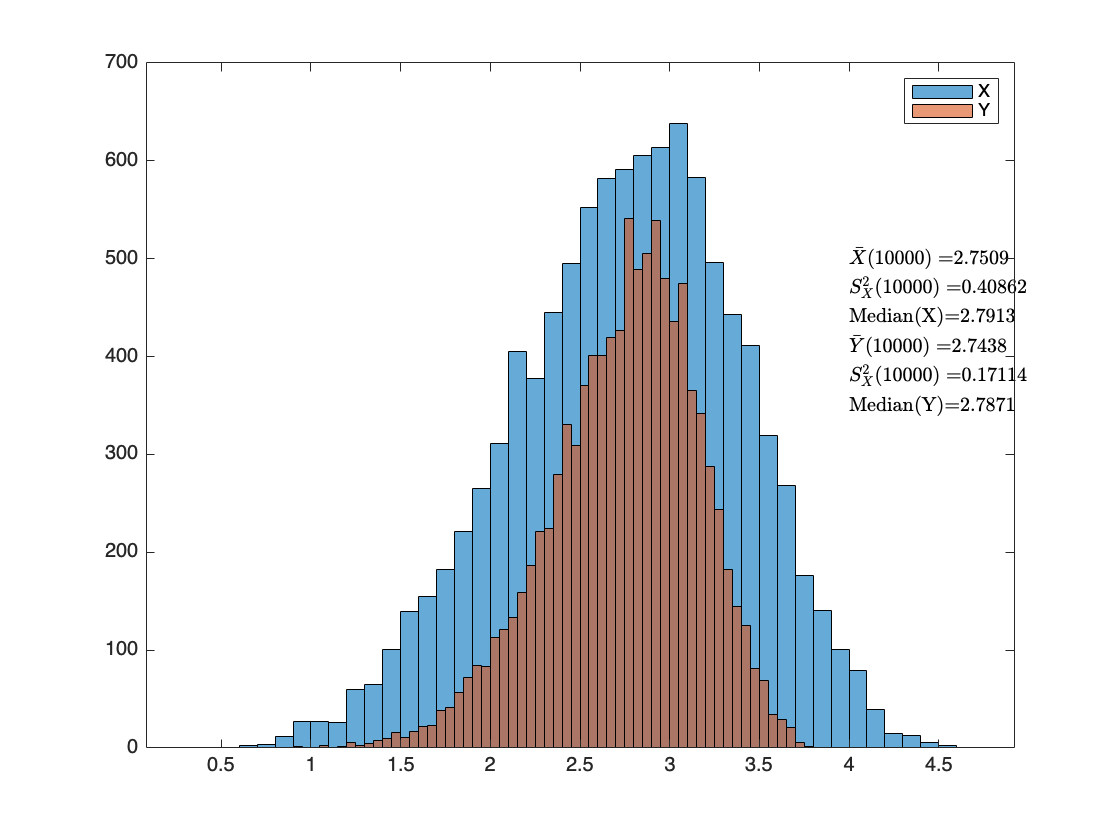

NX=10000;
NY=10000;
X=wblrnd(3,5,1,NX);
Y=wblrnd(3,8,1,NY)-3*(log(2)^(1/8))+3*(log(2)^(1/5));% Correct medians
figure;
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(4,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(4,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(4,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(4,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(4,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(4,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

We then see that despite the fact that the medians are the same/close we still find a significant difference

[p,h,stats] = ranksum(X,Y)

p = 0.0030

h = logical
   1


stats = struct with fields:
       zval: 2.9722
    ranksum: 101218431


We shouldn't get a significant result if we want to test the central tendency of distributions, but we do. This will even get worse if the shapes are different. Hence the rank sum test, thests whether the distributions are the same. In case the distributions have the same shape and the same spread, the rank sum test will indeed test whether the central tendency of the distributions is the same.

### Same distribution, other central tendency

Obviously this will give a significant result

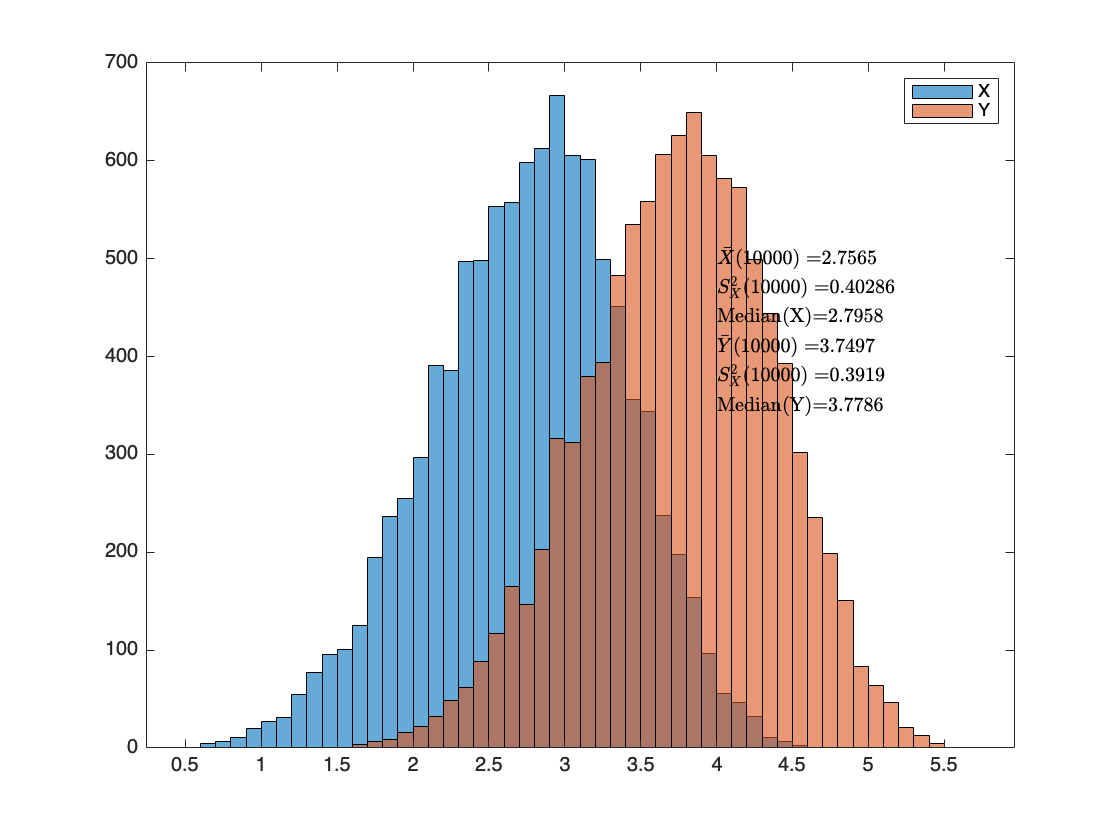

NX=10000;
NY=10000;
X=wblrnd(3,5,1,NX);
Y=wblrnd(3,5,1,NY)+1;
figure;
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(4,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(4,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(4,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(4,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(4,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(4,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

[p,h,stats] = ranksum(X,Y)

p = 0

h = logical
   1


stats = struct with fields:
       zval: -89.8057
    ranksum: 63341057


### Two symmetric distributions with same central tendency

An interesting case, where we have two symmetric distributions. In this particular case, no significant result will be obtained. This is logical from how the ranksums are computed.

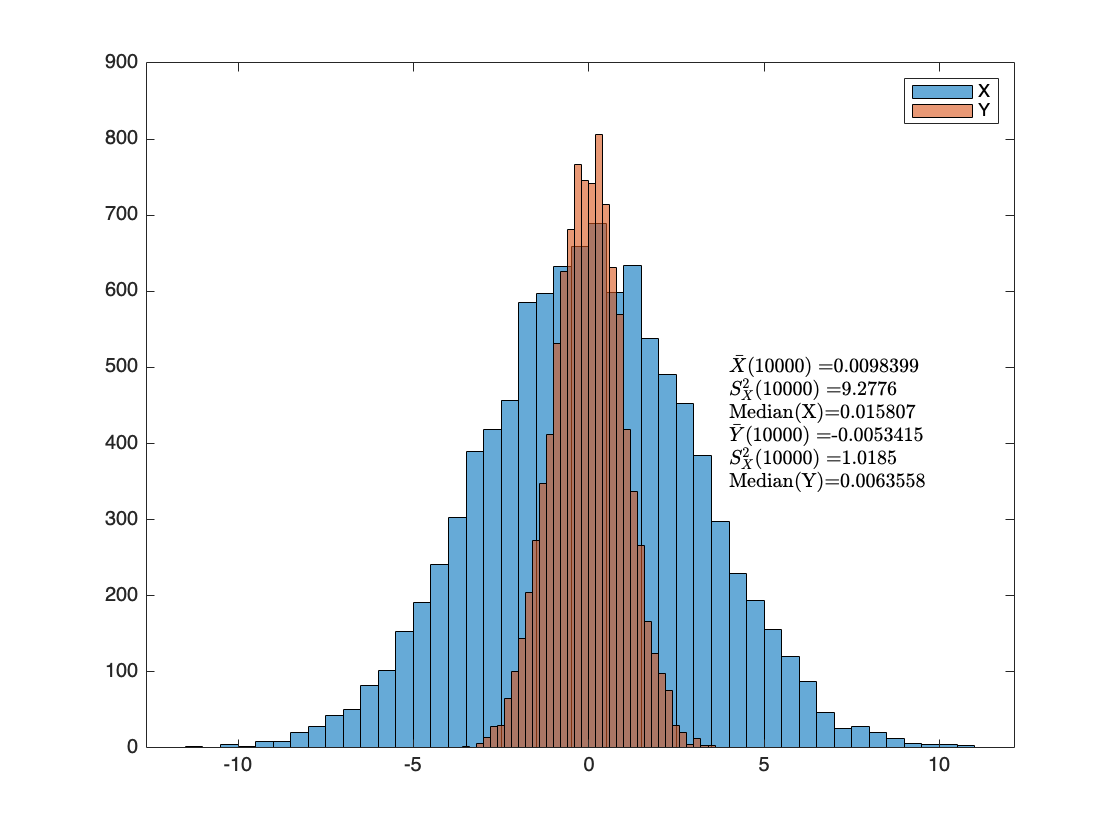

NX=10000;
NY=10000;
X=3*randn([1,NX]);
Y=randn([1,NY]);
figure;
histogram(X)
hold on;
histogram(Y)
legend({'X','Y'})
text(4,500,['$\bar{X}(' num2str(length(X)) ')=$' num2str(mean(X))],'Interpreter','latex')
text(4,470,['$S^2_X(' num2str(length(X)) ')=$' num2str(var(X))],'Interpreter','latex')
text(4,440,['Median(X)=' num2str(median(X))],'Interpreter','latex')
text(4,410,['$\bar{Y}(' num2str(length(Y)) ')=$' num2str(mean(Y))],'Interpreter','latex')
text(4,380,['$S^2_X(' num2str(length(Y)) ')=$' num2str(var(Y))],'Interpreter','latex')
text(4,350,['Median(Y)=' num2str(median(Y))],'Interpreter','latex')

[p,h,stats] = ranksum(X,Y)

p = 0.5814

h = logical
   0


stats = struct with fields:
       zval: 0.5513
    ranksum: 100230074
